# ECEN2250 HW5 Problem 5g: Plotting inverting summer voltages

Ian Faber

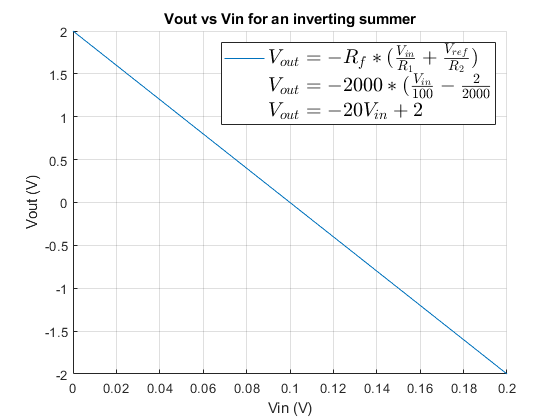

clc; clear; close all;

vIn = 0:0.01:0.2;
vRef = -2;
Rf = 2000;
R1 = 100;
R2 = 2000;

voltRelation = @(v) -Rf*((v/R1)+(vRef/R2));

figure
hold on;
grid on;
plot(vIn, voltRelation(vIn));
plot(0,0,'white')
plot(0,0,'white')
title("Vout vs Vin for an inverting summer")
xlabel("Vin (V)");
ylabel("Vout (V)");
legend("$V_{out} = -R_f*(\frac{V_{in}}{R_1} + \frac{V_{ref}}{R_2})$", ...
       "$V_{out} = -2000*(\frac{V_{in}}{100} - \frac{2}{2000}$", ...
       "$V_{out} = -20V_{in}+2$","Interpreter","latex","FontSize",15)